# MATLABthon 27/05/23, Politecnico di Milano

#### *Authors: Bonfadini Matteo, Venturelli Riccardo*

GitHub repository link here

## Our goal

Con questo *LiveScript* sarai in grado di disegnare a tuo piacere con *MATLAB*, quindi divertiti!

## Preparing data

Rileviamo i dati con MATLAB Mobile:

clear; close all; clc;

m = mobiledev("realme 8 Pro"); % modificare con il nome del tuo device
m.Logging = 1;

**NB: **modificare `mobiledev` con il nome del tuo device.

## Coding the model

Inseriamo i dati iniziali:

first = 1;
i = 1;
angx = 0;
angy = 0;
angz = 0;
a = 0.6;
datax = 0;
datay = 0;
durata = 10;

Creiamo il nostro plot considerando i dati rilevati dall'applicaizone* MATLAB Mobile*, in particolare:

- usiamo l'angolo di orientamento del telefono

- applichiamo una media mobile dei valori per filtrare le imprecisioni

Il risultato è il seguente:

disp("Posiziona il telefono, sei pronto a disegnare?");

Posiziona il telefono, sei pronto a disegnare?


pause(3)
disp("Vai!")

Vai!


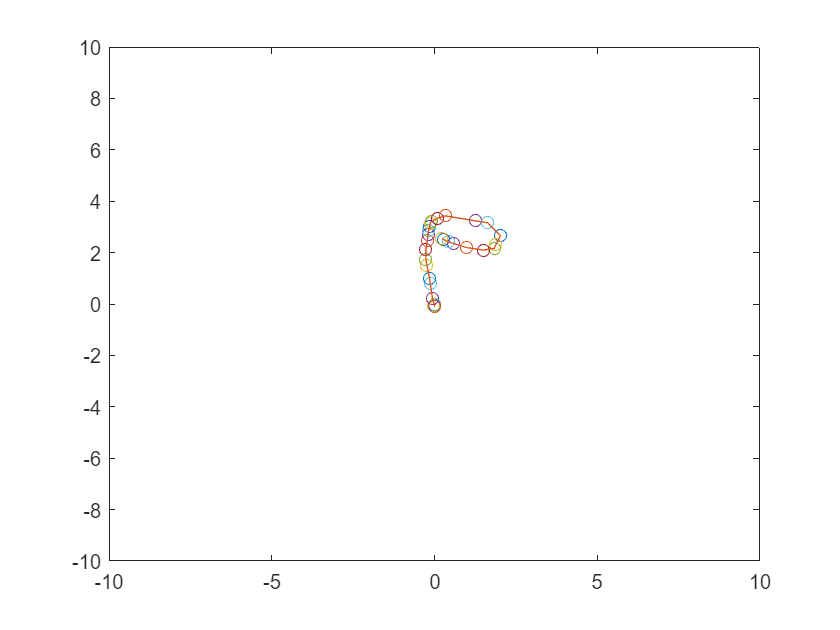

figure()
tempoInizio = tic;

while toc(tempoInizio) < durata

    % Rilevamento dei dati
    angx_r = m.Orientation(1)*pi/180;
    angy_r = m.Orientation(2)*pi/180;
    angz_r = m.Orientation(3)*pi/180;
    
    % Inizializzazione
    if(first == 1)
        angx0 = angx_r;
        angy0 = angy_r;
        angz0 = angz_r;
        t0 = clock;
        first = 0;
    end
    
    % Filtro - media mobile
    angx = (1-a)*angx + a*(angx_r-angx0);
    angy = (1-a)*angy + a*(angy_r-angy0);
    angz = (1-a)*angz + a*(angz_r-angz0);

    % Posizione corrente del cursore
    d = 10;
    pointy = d*tan(-angy);
    pointx = d*tan(angx);
    
    % La salviamo per tenerne traccia nel tempo
    datax(i) = pointx;
    datay(i) = pointy;
    datat(i) = round(etime(clock,t0) * 1000)/1000;
    i = i+1;

    % Plottiamo il disegno
    plot(datax,datay)
    hold on
    plot(pointx,pointy,'o')
    xlim([-10,10]);
    ylim([-10,10]);
    pause(0.1)
end

## Saving your draw

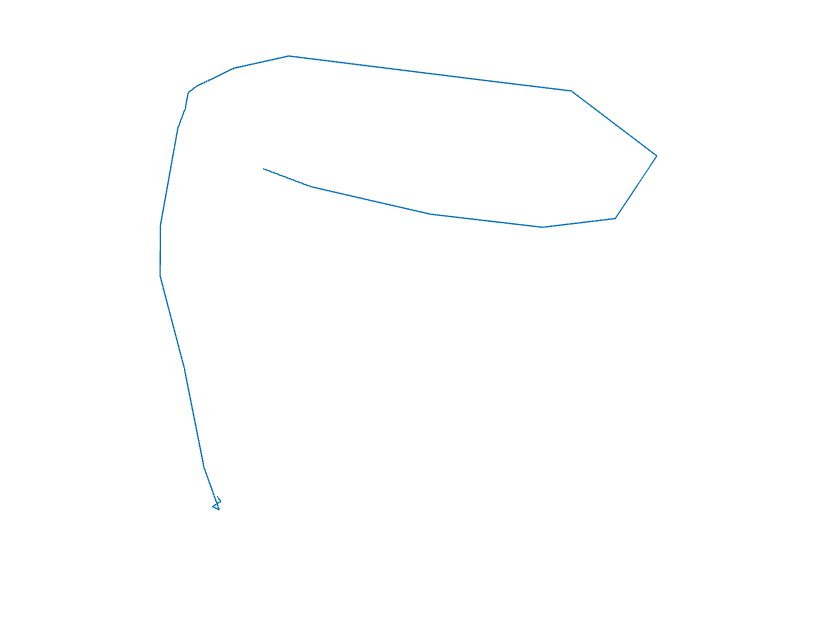

figure()
plot(datax,datay)
axis off
exportgraphics(gcf, 'plot_image.png', 'Resolution', 50);

## Verso orizzonti più ampi

Questo non è altro ch un punto di partenza. Una volta catturata l'immagine, si può addestrare un modello di reti neurali capace di riconoscore un determinato set di disegni. 

Per via del fattore tempo, quest'ultima parte vuole essere solo uno spunto, non è stata ancora implementata completamente.

Supponiamo per esempio di voler disegnare delle lettere. Allora il training del modello potrebbe essere il seguente:

letter = table();
letter.X = datax';
letter.Y = datay';
letter.Time = datat';

preprocess_letter = preprocess(letter);
features_letter = extractfeatures(preprocess_letter);

Carico il modello già allenato per il riconoscimento delle lettere dalla 'a' alla 'z':

load KNNmodel.mat
predLetter = predict(kNNmodel,features_letter);
disp("la lettera disegnata è: ",predLetter);

Trasformazioni sui dati dell'immagine per estrarre la caratteristiche per la classificazione:

function data = preprocess(data)
% Normalize time [0 1]
data.Time = (data.Time - data.Time(1))/(data.Time(end) - data.Time(1));
% Fix aspect ratio
data.X = 1.5*data.X;
% Center X & Y at (0,0)
data.X = data.X - mean(data.X,"omitnan");
data.Y = data.Y - mean(data.Y,"omitnan");
% Scale to have bounding box area = 1
scl = 1/sqrt(range(data.X)*range(data.Y));
data.X = scl*data.X;
data.Y = scl*data.Y;
% Calculate derivatives
data.dXdT = [NaN;diff(data.X)./diff(data.Time)];
data.dYdT = [NaN;diff(data.Y)./diff(data.Time)];
data.dXdT(isinf(data.dXdT)) = NaN;      % Infinite value => same values in data.Time
data.dYdT(isinf(data.dYdT)) = NaN;      % => derivative calculation is meaningless
% Smooth derivatives using a moving average
n = round(0.1*numel(data.Time));
data.dXdT = movmean(data.dXdT,n);
data.dYdT = movmean(data.dYdT,n);
end


function feat = extractfeatures(letter)
% Correlations between signals (not including time)
c = corrcoef(letter{:,2:end},"Rows","pairwise");
% Set some parameters for finding local mins/maxes
mp = 0.1;
derivscale = 2;
% Calculate features
feat = [range(letter.Y)/range(letter.X),...                             % aspect ratio
    mad(letter.X), mad(letter.Y),...                                    % deviation for X & Y
    mean(letter.dXdT,"omitnan"),mad(letter.dXdT),...                    % mean and deviation
    mean(letter.dYdT,"omitnan"),mad(letter.dYdT),...                    %   for X' & Y'
    c(1,2:end),c(2,3:end),c(3,4:end),c(4,end),...                       % correlations
    nnz(islocalmin(letter.X,"MinProminence",mp)),...                    % number of local
    nnz(islocalmax(letter.X,"MinProminence",mp)),...                    %   min/max for X & Y
    nnz(islocalmin(letter.Y,"MinProminence",mp)),...
    nnz(islocalmax(letter.Y,"MinProminence",mp)),...
    nnz(islocalmin(letter.dXdT,"MinProminence",derivscale*mp)),...      % number of local
    nnz(islocalmax(letter.dXdT,"MinProminence",derivscale*mp)),...      %   min/max for X' & Y'
    nnz(islocalmin(letter.dYdT,"MinProminence",derivscale*mp)),...
    nnz(islocalmax(letter.dYdT,"MinProminence",derivscale*mp))];

% Combine features together into a table
feat = array2table(feat,"VariableNames",...
    ["AspectRatio",...
    "MADX","MADY","AvgU","MADU","AvgV","MADV",...
    "CorrXY","CorrXP","CorrXU","CorrXV",...
    "CorrYP","CorrYU","CorrYV","CorrPU","CorrPV","CorrUV",...
    "NumXMin","NumXMax","NumYMin","NumYMax",...
    "NumUMin","NumUMax","NumVMin","NumVMax"]);

end